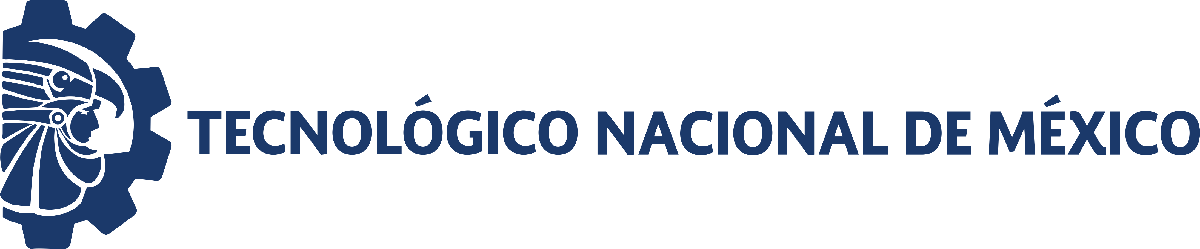                                 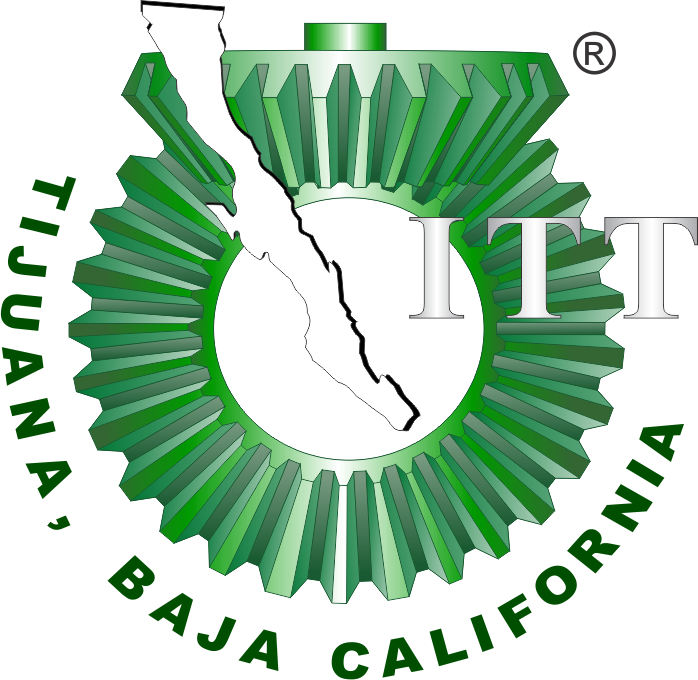

# Práctica 1: Diseño de controladores 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

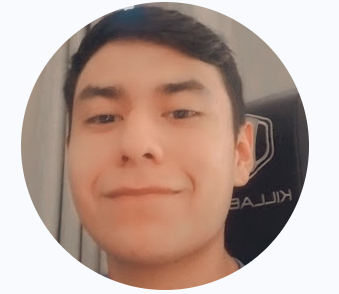

Nombre del alumno: Cesar Andres Ramirez Diaz

Número de control: 21212173

Correo institucional: l21212173**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sysp1';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';
Controlador = 'PID';

## Respuesta al escalón

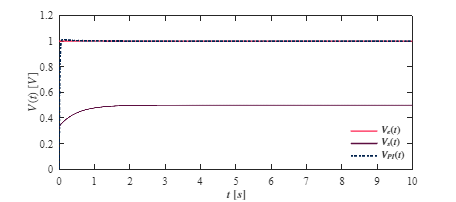

Signal1 = 'Escalon';
set_param('sysp1/S1','sw','1');
set_param('sysp1/Pao(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.VPID,Signal1)

## Respuesta al impulso

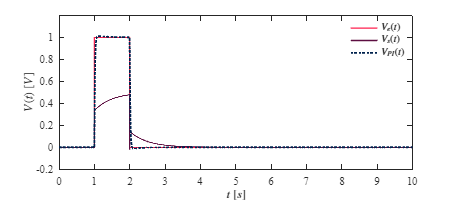

Signal1 = 'Impulso';
set_param('sysp1/S1','sw','0');
set_param('sysp1/Pao(t)','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.VPID,Signal1)

## Respuesta a la rampa

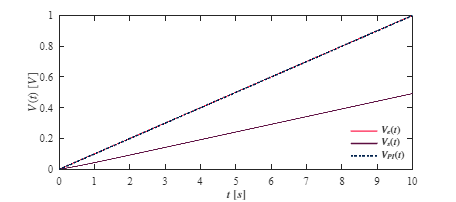

Signal1 = 'Rampa';
set_param('sysp1/S2','sw','1');
set_param('sysp1/Pao(t)','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.VPID,Signal1)

## Respuesta a la función sinusoidal

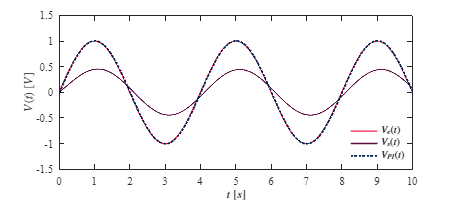

Signal1 = 'Sinusoidal';
set_param('sysp1/S2','sw','0');
set_param('sysp1/Pao(t)','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.VPID,Signal1)

## Función: Respuesta a las señales

function plotsignals(t, Ve, Vs, VPID, Signal1)
    set(figure(), 'Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position',[1,1,18,8])
    set(gca, 'FontName', 'Times New Roman')
    fontsize(12, 'points')
    rosa = [255/255, 32/255, 78/255];
    morado = [93/255, 14/255, 65/255];
    azul = [0/255, 34/255, 77/255];
    hold on; grid off; box on

    t = t(:); 
    
    % Convertir objetos timeseries a arreglos numéricos
    if isa(Ve, 'timeseries'), Ve = Ve.Data(:); end
    if isa(Vs, 'timeseries'), Vs = Vs.Data(:); end
    if isa(VPID, 'timeseries'), VPID = VPID.Data(:); end


    plot(t, Ve, 'LineWidth', 1.5,'Color',rosa)
    plot(t, Vs, 'LineWidth', 1.5,'Color', morado)
    plot(t, VPID,':', 'LineWidth', 2,'Color', azul)
    
    xlabel('$t$ $[s]$',  'Interpreter','Latex')
    ylabel('$V(t)$ $[V]$',  'Interpreter','Latex')

    L = legend('$V_e(t)$','$V_s(t)$', '$V_{PI}(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','Off')
    
    if Signal1 == "Escalon lc"
        xlim([-0.2, 10]); xticks(0:1:10)
        ylim([0, 1.2]); yticks(0:0.1:1.2)
    
    elseif Signal1 == "Impulso lc"
        xlim([0, 10]); xticks(0:1:10)
        ylim([-0.2, 1.2]); yticks(-0.2:0.1:1.2)

    elseif Signal1 == "Rampa lc"    
        xlim([0, 10]); xticks(0:1:10)
        ylim([-0.05, 1.1]); yticks(0:0.1:1.1)
    
    elseif Signal1 == "Sinusoidal lc"
        xlim([0, 10]); xticks(0:1:10)
        ylim([-1.2, 1.2]); yticks(-1.2:0.2:1.2)

    end
   exportgraphics(gcf,[Signal1,'.pdf'], 'ContentType', 'Vector')


    
end